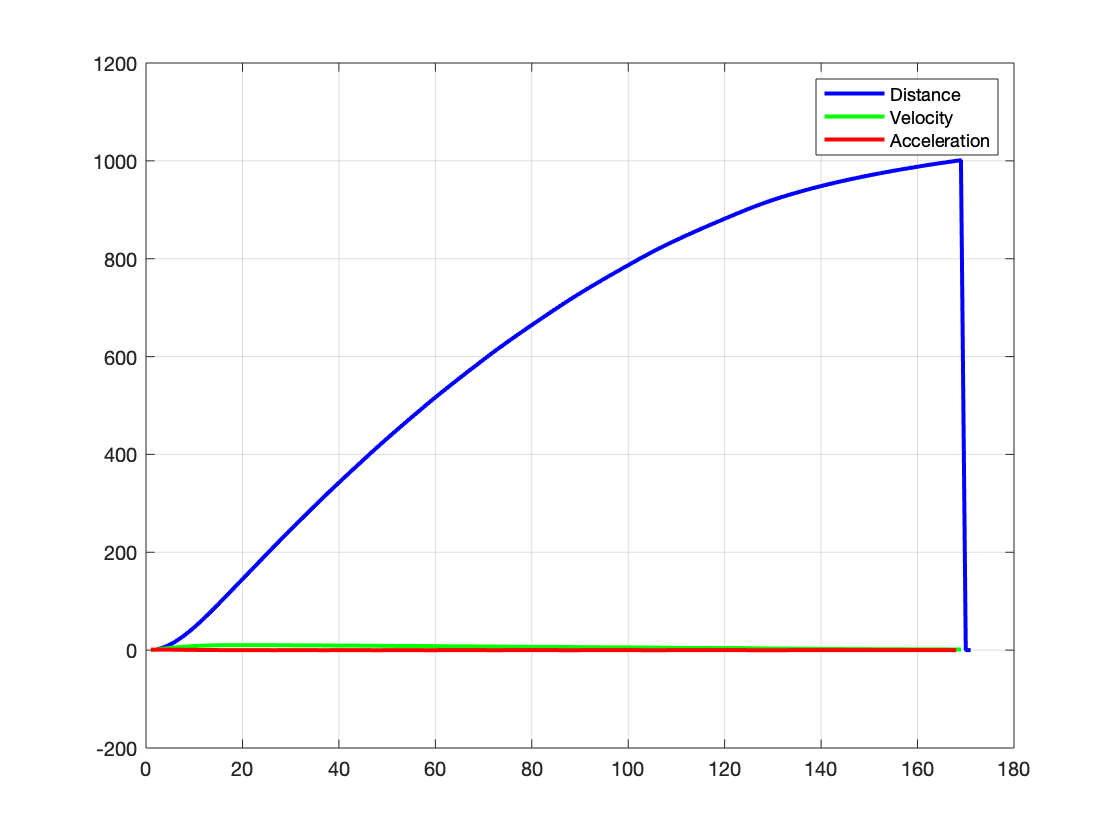

%%%%%%%%%%%%%%%%%%%%%%%%%% Balloon house %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all;

%%%%%%%%%%%%%%%%%%%%%%% Variables and equations %%%%%%%%%%%%%%%%%%%%%%

r = 22.09626871;   %Radius of the balloon
m_balloon = 300; %Mass of the balloon
m_house = 40000; %Mass of the house
g = 9.82; %Gravity
density_air = 1.2; %Density of air
density_helium = 0.1785;  %Density of helium
m_tot = m_balloon + m_house; %Total mass
Cross_Area = (r^2 * pi); %Cross area of the sphere
V = (4*pi*r^3)/3; %Volume of spehere
c = 0.45; %Coefficient for air resistance of a sphere
Press_air = 100000; %Pascal
Temp = 273.15; %0 degrees in Kelvin 
Mol_air = 0.029; 
Gas_air = 8.3145;
h = 1; %Stepsize
x = 0:h:170; %Range of x
y = zeros(size(x)); %Allocate the result y
n = numel(y); %Number of y values
y(1) = 0;  %Intial value of distance
v(1) = 0; %Initial value of Velocity
a(1) = 0; %Initial value of acceleration

F1 = m_tot * g; %Gravity force

%%%%%%%%%%%%%%%%%%%%%% For loop %%%%%%%%%%%%%%%%%%%%%%%%%%%

for t=1:n-1
    
    
    if 0<=y(t) && y(t)<100
        density_air = ((100000-625)* Mol_air)/(Gas_air*((20-0.4)+Temp));
     
    elseif 100<=y(t) && y(t)<200
        density_air = ((100000-1875)* Mol_air)/(Gas_air*((20-1.2) + Temp));
        
    elseif 200<=y(t) && y(t)<300
        density_air = ((100000-3125)* Mol_air)/(Gas_air*((20-2) + Temp));
        
    elseif 300<=y(t) && y(t)<400
         density_air = ((100000-4375)*Mol_air)/(Gas_air*((20-2.8) + Temp));        
       
    elseif 400<=y(t) && y(t)<500
        density_air = ((100000-5625)*Mol_air)/(Gas_air*((20-3.6) + Temp));
        
    elseif 500<=y(t) && y(t)<600
        density_air = ((100000-6875)*Mol_air)/(Gas_air*((20-4.4) + Temp));
        
    elseif 600<=y(t) && y(t)<700
        density_air = ((100000-8125)*Mol_air)/(Gas_air*((20-5.2) + Temp)); 

    elseif 700<=y(t) && y(t)<800
        density_air = ((100000-9375)*Mol_air)/(Gas_air*((20-6.0)+Temp));
         
    elseif 800<=y(t) && y(t)<900
        density_air = ((100000-10625)*Mol_air)/(Gas_air*((20-6.8)+Temp));
        
    elseif 900<=y(t) && y(t)<1000
        density_air = ((100000-11875)*Mol_air)/(Gas_air*((20-7.6)+Temp));
        
    else
        break;
      
   end
   
 %%%%%%%%%%%%%%%%%%%%%% Forces calculation %%%%%%%%%%%%%%%%%%%%%%%%%%%
   
F_air = ((c * density_air * Cross_Area)*(v(t)^2))/2; %Air resistance
F_up = density_air * V * g; 
F_down = (m_balloon + V * density_helium) * g;
F_lift = F_up - F_down; %Force of the balloon
Fnetto = -F1+F_lift-F_air; %Total forces impacting the balloon

a(t) = (1/(m_tot) * Fnetto); %Acceleration
v(t+1) = v(t) + h * a(t); %Velocity
y(t+1) = y(t) + h * v(t+1); %Distance 

end

%%%%%%%%%%%%%%%%%%%%%% Plot simulation %%%%%%%%%%%%%%%%%%%%%%%%%%

figure(1)
plot(y, 'b', 'LineWidth',2); 
hold on; grid on;

plot(v, 'g', 'LineWidth',2)

plot(a, 'r', "LineWidth",2)

legend('Distance', 'Velocity', 'Acceleration')